** 변수끼리의 충돌 방지를 위해서 2번 문제를 제외한 문제에서는 문제 번호 기준으로 인덱싱했습니다**

<1번 문제>

A1 = [...
    1 4 2;...
    2 4 100;...
    7 9 7;...
    3 pi 42];
B1 = log(A1);

1-(a)

B1(2,:)

ans =     0.6931    1.3863    4.6052


1-(b)

sum(B1(2,:))

ans = 6.6846

1-(c)

C1 = B1(:,2).*A1(:,1)

C1 =     1.3863
    2.7726
   15.3806
    3.4342


1-(d)

max(C1)

ans = 15.3806

1-(e)

sum(A1(1,:)./B1(1:3,3).')

ans = 3.3391

<2번 문제>

v0 = 50;
A = 50 * pi / 180; %라디안변환
g = 9.81;

2-(a)

y값이 다시 0이 될 때의 t값을 구하면 그것이 발사체의 충돌시간, t_hit이다.

(v0*sinA)t - (1/2)gt^2 = t * {(v0*sinA) - (1/2)gt}이므로

(v0*sinA) - (1/2)gt = 0 이 될 때의 t값이 t_hit값이다.

즉, t_hit = (v0*sinA) * 2 / g

t_hit = (v0*sin(A)) * 2 / g;
disp('t_hit:')

t_hit:


disp(t_hit)

    7.8088



높이가  최대가 되는 시점은 총 충돌 시간의 절반이 지난 시점이므로

y = (v0*sinA)t - (1/2)gt^2 의 t에 t_hit/2를 대입한 y 값이 y_max이다.

즉, y_max = (v0*sinA)(t_hit/2) - (1/2)g(t_hit/2)^2

y_max = (v0*sin(A))*(t_hit/2) - (1/2)*g*(t_hit/2)^2;
disp('y_max:')

y_max:


disp(y_max)

   74.7737



2-(b)

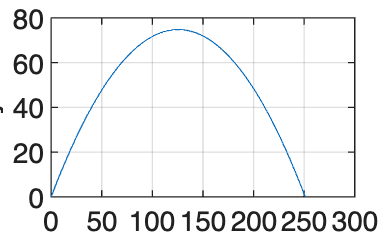

t = 0:0.01:t_hit;
x = (v0*cos(A))*t;
y = (v0*sin(A))*t - (1/2)*g*t.^2;
plot(x,y)
xlabel('x')
ylabel('y')
grid on

<3번 문제>

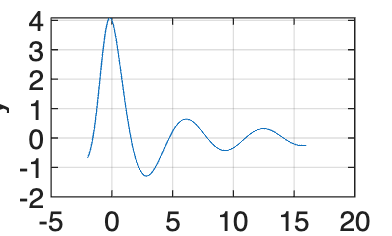

x3 = (-2):0.01:16;
y3 = (4*cos(x3))./(x3+exp(-0.75*x3));
plot(x3,y3)
xlabel('x')
ylabel('y')
grid on

<4번 문제>

price = [300;550;400;250;500];
num = [...
    5 4 6;...
    3 2 4;...
    6 5 3;...
    3 5 4;...
    2 4 3];

4-(a)

res4 = price .* num

res4 =         1500        1200        1800
        1650        1100        2200
        2400        2000        1200
         750        1250        1000
        1000        2000        1500


4-(b)

disp('5월 총 소비량:')

5월 총 소비량:


disp(sum(res4(:,1)))

        7300



disp('6월 총 소비량:')

6월 총 소비량:


disp(sum(res4(:,2)))

        7550



disp('7월 총 소비량:')

7월 총 소비량:


disp(sum(res4(:,3)))

        7700



4-(c)

disp('재료1 총 소비량:')

재료1 총 소비량:


disp(sum(res4(1,:)))

        4500



disp('재료2 총 소비량:')

재료2 총 소비량:


disp(sum(res4(2,:)))

        4950



disp('재료3 총 소비량:')

재료3 총 소비량:


disp(sum(res4(3,:)))

        5600



disp('재료4 총 소비량:')

재료4 총 소비량:


disp(sum(res4(4,:)))

        3000



disp('재료5 총 소비량:')

재료5 총 소비량:


disp(sum(res4(5,:)))

        4500



4-(d)

disp('총 소비량:')

총 소비량:


disp(sum(res4(:)))

       22550



<5번 문제>

5-(a)

a5a = [5 0 -3 7 10];
b5a = [4 -7 9 2];
product = conv(a5a,b5a)

product =     20   -35    33    59   -36   -13   104    20


5-(b)

a5b = [5 -7 2 8];
b5b = [6 3 -2];
[quotient, remainder] = deconv(a5b,b5b)

quotient =     0.8333   -1.5833


remainder =          0         0    8.4167    4.8333


5-(c)

x5 = 5;
res5 = (36*x5^3 - 8*x5^2 + 2)/(36*x5^3 - 5*x5^2 + 4*x5 - 3)

res5 = 0.9795

<7번 문제>

7-(a)

bridge(1).location = 'Smith St.';
bridge(1).max = 80;
bridge(1).year = 1928;
bridge(1).remain = 2025;

bridge(2).location = 'Hope Ave.';
bridge(2).max = 90;
bridge(2).year = 1950;
bridge(2).remain = 2027;

bridge(3).location = 'Clark St.';
bridge(3).max = 85;
bridge(3).year = 1933;
bridge(3).remain = 2024;

bridge(4).location = 'North Rd.';
bridge(4).max = 100;
bridge(4).year = 1960;
bridge(4).remain = 2023;

7-(b)

bridge(3).remain = 2026;

7-(c)

bridge(5).location = 'Shore Rd.';
bridge(5).max = 85;
bridge(5).year = 1997;
bridge(5).remain = 2022;


